% Ising Hessian notes
X = PauliI(1, 1, 1);
Y = PauliI(1, 1, 2);
Z = PauliI(1, 1, 3);
I = eye(2);




N = 10;
g = 0.5;


% Via exact diagonalization
[H, Hloc] = hIM(1, g, 0, N, 'PBC');
I = 2; % index of local player
h = Hloc(:, :, I);

Z = @(b) trace(expm(-b*H));


A = @(b) 2 * trace(PauliI(N, I, 3) * PauliI(N, I+1, 3) * expm(-b * H));
B = @(b) 2 * g * trace(PauliI(N, I, 1) * expm(-b * H));
C = @(b) trace(PauliI(N, I, 2) * PauliI(N, I+1, 3) * expm(-b * H));

M = @(b) [
    A(b), 0, 0;
    0, A(b)+B(b), -C(b)+1i*g;
    0, conj(-C(b)+1i*g), B(b)]/Z(b);

lam = @(b) eig(M(b), 'vector')

lam = function_handle with value:
    @(b)eig(M(b),'vector')



% Some approximation to numerical values


T = linspace(0.1, 1, 10) % reduced temperature

T =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


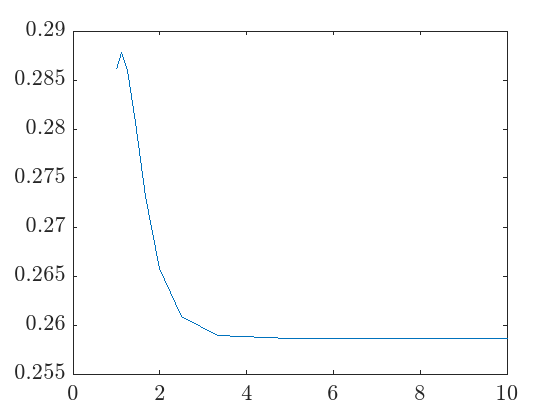

bset = 1./T;

lams = zeros(3, length(T));

for i = 1:length(T)
    lams(:, i) = lam(bset(i));
end
figure()
plot(bset, min(lams))
hold off

% Verify the thermal average of energy density

eta = 1;

eps = @(p, g) sqrt(1 + g^2 - 2*g*cos(kk(N, p, 0)));
% Z1 = @(b) 1/2*exp(b*sum(eps(0))) * (prod(1+exp(-2*b*eps(0))) + eta*prod(1-exp(-2*b*eps(0)))) + 1/2*exp(b*sum(eps(1))) * (prod(1+exp(-2*b*eps(1))) + eta*prod(1-exp(-2*b*eps(1))));
Z1 = @(b) 1/2 * (prod(1+exp(-2*b*eps(0, g))) + eta*prod(1-exp(-2*b*eps(0, g)))) + 1/2 * (prod(1+exp(-2*b*eps(1, g))) + eta*prod(1-exp(-2*b*eps(1, g))));
% eps = @(p) sqrt(1 + g^2 - 2*g*cos(kk(N, p, 1)));
f10 = @(p, mu, b) f(p, mu, eps, eta, '10', b, Z1);
f01 = @(p, mu, b) f(p, mu, eps, eta, '01', b, Z);
% expectation of energy density

T = linspace(0.1, 2, 20);


Eh = zeros(size(T));
energy = zeros(size(T));
b = T.^(-1);

for i = 1:size(T, 2)
    E = eps(0);
    for mu = 1:N
        Eh(i) = Eh(i) + E(mu)*(2*f10(0, mu, b(i))-1);
    end
    E = eps(1);
    for mu = 1:N
        Eh(i) = Eh(i) + E(mu)*(2*f10(1, mu, b(i))-1);
    end
    energy(i) = trace(H * expm(-b(i)*H))/Z(b(i))/N;
end
Eh = Eh/N;


energy(1)

ans = -1.0635

Eh(1)

ans = -2.1271

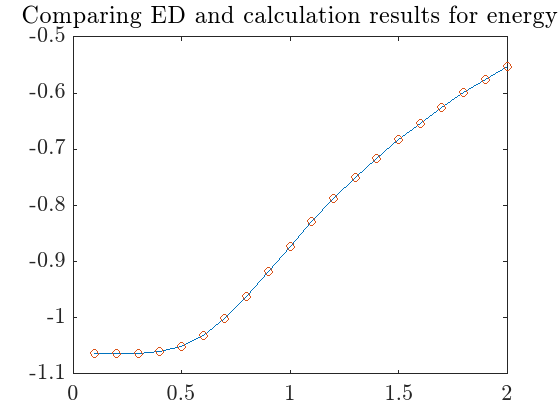

figure()
plot(T, energy)
hold on
plot(T, Eh + (energy(1)-Eh(1)), 'o')
hold off
title('Comparing ED and calculation results for energy')

% figure()
% plot(T, Eh./energy)

## Consistency of ED and analytics for finite-temperature Hessian

The Hessian at finite temperature is again a $3\times 3$ matrix, of the following form


$$\mathrm{HS}_i=\left(\begin{array}{ccc}
2\left\langle\hat{Z}_i \hat{Z}_{i+1}\right\rangle & i\left\langle\hat{Z}_{i+1}\right\rangle-g\left\langle\hat{Y}_i\right\rangle & -\left\langle\hat{X}_i \hat{Z}_{i+1}\right\rangle-g\left\langle\hat{Z}_i\right\rangle \\
-i\left\langle\hat{Z}_{i+1}\right\rangle+g\left\langle\hat{Y}_i\right\rangle & 2\left\langle\hat{Z}_i \hat{Z}_{i+1}\right\rangle+2 g\left\langle\hat{X}_i\right\rangle & -\left\langle\hat{Y}_i \hat{Z}_{i+1}\right\rangle+i g \\
-\left\langle\hat{X}_i \hat{Z}_{i+1}\right\rangle-g\left\langle\hat{Z}_i\right\rangle & \left\langle\hat{Y}_i \hat{Z}_{i+1}\right\rangle-i g & 2 g\left\langle\hat{X}_i\right\rangle
\end{array}\right)$$


### ED calculation

In the following we first evaluate explicitly these one- and two-body correlators. We observe that $(1,2), (1,3)$ elements and their conjugates vanishes by symmetry. Thus we are left with a finite-temperature Hessian that is completely determined by the correlators $\langle ZZ\rangle, \langle YZ \rangle$ and $\langle X \rangle$. (also used translational symmetry)


$$\mathrm{HS}_i=\left(\begin{array}{ccc}
2\left\langle\hat{Z}_i \hat{Z}_{i+1}\right\rangle &0 &0 \\
0 & 2\left\langle\hat{Z}_i \hat{Z}_{i+1}\right\rangle+2 g\left\langle\hat{X}_i\right\rangle & -\left\langle\hat{Y}_i \hat{Z}_{i+1}\right\rangle+i g \\
0& \left\langle\hat{Y}_i \hat{Z}_{i+1}\right\rangle-i g & 2 g\left\langle\hat{X}_i\right\rangle
\end{array}\right)$$


% general thermal average
expec = @(b, O) trace(O * expm(-b*H))/trace(expm(-b*H));

eX = @(b) expec(b, PauliI(N, 1, 1));
eY = @(b) expec(b, PauliI(N, 1, 2));
eZ = @(b) expec(b, PauliI(N, 1, 3));

eXZ = @(b) expec(b, PauliI(N, 1, 1)*PauliI(N, 2, 3));
eYZ = @(b) expec(b, PauliI(N, 1, 2)*PauliI(N, 2, 3));
eZZ = @(b) expec(b, PauliI(N, 1, 3)*PauliI(N, 2, 3));

M = zeros(3);
T = linspace(0.1, 4, 20);
b = T.^(-1);
lam = zeros(3, size(b, 2));
% Compute the Hessian eigenvalues
for i = 1:size(b, 2)
    M(1, 1) = 2*eZZ(b(i));
    M(2, 2) = 2*eZZ(b(i)) + 2*g*eX(b(i));
    M(3, 3) = 2*g*eX(b(i));
    M(2, 3) = -eYZ(b(i)) + 1i*g;
    M(3, 2) = eYZ(b(i)) - 1i*g;

    lam(:, i) = eig(M);
end


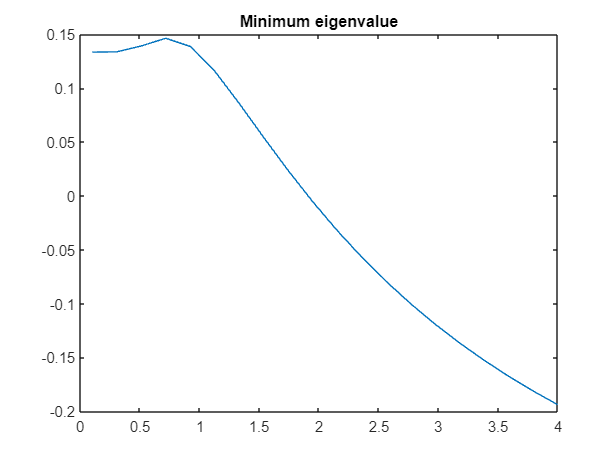

ZZ = zeros(1, size(b, 2));
for i = 1:size(b, 2)
    ZZ(i) = 2*eZZ(b(i));
end
% plot(T, ZZ)


figure()
plot(b.^(-1), min(lam))
title('Minimum eigenvalue of Hessian')

% figure()
% plot(T, lam([3], :))
% title('max eigenvalues of the Hessian')

For now let's verify that the finite temperature correlation functions are correct. For example, we have


$$\langle X \rangle_\beta = 1-2 \langle c_i^\dagger c_{i}\rangle_\beta = 1-\frac{2}{N} \sum_{\sigma = \pm, k}\left( \cos(\theta_k) \langle \gamma_k^\dagger \gamma_k\rangle_{\beta,\sigma} + \sin^2 \frac{\theta_k}{2}\right)
$$


where the Bogoliubon number operator at the $\sigma$ parity sector is


$$\frac{e^{-2\beta \epsilon_{\sigma}(k)}}{2} \frac{\prod_{q\neq k} \left(1 + e^{-2\beta \epsilon_\sigma(k)}\right) - \prod_{q\neq k} \left(1 - e^{-2\beta \epsilon_\sigma(k)}\right) }{\sum_{\sigma}\left[ \prod_{q} \left(1 + e^{-2\beta \epsilon_\sigma(k)}\right) + \prod_{q} \left(1 - e^{-2\beta \epsilon_\sigma(k)}\right)  \right]}$$


(The denominator is the full partition function of the system)

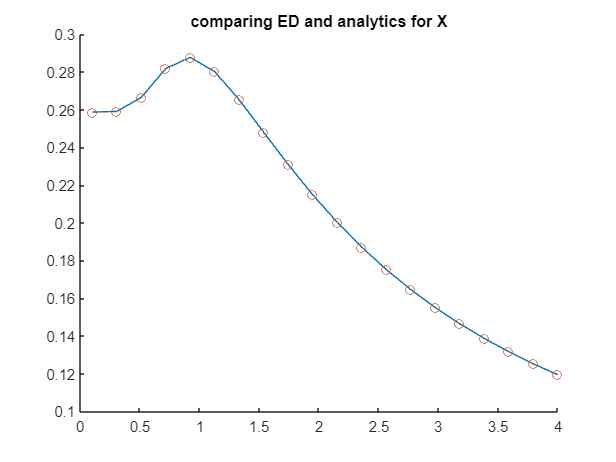


X_ed = zeros(1, size(b, 2));
X_calc = zeros(1, size(b, 2));
for i = 1:size(b, 2)
    % ED result for <X>
    X_ed(i) = eX(b(i));

    % calculation for <X>
    % create a vector
    vec = zeros(2, N); % two rows for two parity sectors
    for p = [0, 1]
        K = kk(N, p, 0);
        E = eps(p);
        for mu = 1:N
            vec(p+1, mu) = (g - cos(K(mu)))/E(mu) * single_ptle_excit(b(i), mu, ...
               p, N, eps) + 1/2 - 1/2*((g - cos(K(mu)))/E(mu));
        end
    end
    X_calc(i) = 1/2 * (sum(vec, 'all') * (-2/N))+1;
end
% figure()
% plot(T, X_ed)
% title('ED result of X expectation')
% figure()
% hold on
% plot(T, X_calc)
% title('Calculation of X expectation')
% hold off

figure()
title('comparing ED and analytics for X')
hold on
plot(T, X_ed)
plot(T, X_calc, 'o')
hold off

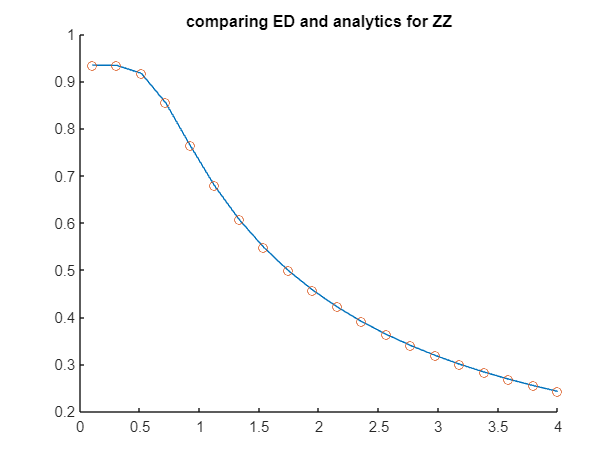

% Also check the ZZ correlations
ZZ_ed = zeros(1, size(b, 2));
ZZ_calc = zeros(1, size(b, 2));

for i = 1:size(b, 2)
    % ED result for <ZZ>
    ZZ_ed(i) = eZZ(b(i));

    vec = zeros(2, N); % two rows for two parity sectors
    for p = [0, 1]
        K = kk(N, p, 0);
        E = eps(p);
        for mu = 1:N
            vec(p+1, mu) = -2*sin(K(mu))^2/E(mu) * (single_ptle_excit(b(i), mu, ...
               p, N, eps) - 1/2)  + 2*cos(K(mu))* (single_ptle_excit(b(i), mu, ...
               p, N, eps)*(g-cos(K(mu)))/E(mu)  + 1/2 - 1/2*(g-cos(K(mu)))/E(mu));
        end
    end
    ZZ_calc(i) = 1/2 * (sum(vec, 'all') * (1/N));
end
% figure()
% plot(T, ZZ_ed)
% title('ED result of ZZ expectation')
% figure()
% hold on
% plot(T, ZZ_calc)
% title('Calculation of ZZ expectation')
% hold off

figure()
title('comparing ED and analytics for ZZ')
hold on
plot(T, ZZ_ed)
plot(T, ZZ_calc, 'o')
hold off

% 
% figure()
% title('difference')
% plot(T, ZZ_ed - ZZ_calc)

M = [1, 2; 3, 1];
[c, d] = eig(M, 'vector')

c =    0.632455532033676  -0.632455532033676
   0.774596669241483   0.774596669241483


d =    3.449489742783178
  -1.449489742783178


We are now at the place to do actual computation of $T_\epsilon(g)$. We define $z_\beta = \langle Z_i Z_{i+1}\rangle_\beta$ and $x_\beta = \langle X_i \rangle_\beta$. The block that gives the desired negative eigenvalue has to be from


$$\left(\begin{array}{cc}
2z_\beta+2 gx_\beta&i g \\
-i g & 2 gx_\beta
\end{array}\right)$$


for which we have the condition

$g^2 - 4g z_\beta x_\beta - 4z_\beta^2 = 0$.

But now $z_\beta$ and $x_\beta$ actually depends on $g$. So this is still a super implicit equation relating $T,g$. We will find the solution by computation

b = linspace(0.001,3,20)

b =     0.0010    0.0536    0.1062    0.1587    0.2113    0.2639    0.3165    0.3691    0.4216    0.4742    0.5268    0.5794    0.6319    0.6845    0.7371    0.7897    0.8423    0.8948    0.9474    1.0000


gset = zeros(size(b));
for i = 1:size(b, 2)
    z = eZZ(b(i));
    x = eX(b(i));
    gset(i) = 2*z * (x + sqrt(x^2+1));
end

gg = linspace(0, 2, 10)

gg =          0    0.2222    0.4444    0.6667    0.8889    1.1111    1.3333    1.5556    1.7778    2.0000


bb = linspace(0, 4, 20)

bb =          0    0.2105    0.4211    0.6316    0.8421    1.0526    1.2632    1.4737    1.6842    1.8947    2.1053    2.3158    2.5263    2.7368    2.9474    3.1579    3.3684    3.5789    3.7895    4.0000


yy = zeros(10, 10);
for i = 1:20
    for j = 1:10
        [x, z] = gen_therm_av(N, bb(i), gg(j));
        yy(i, j) = 2*z + gg(j) * (x - sqrt(x^2+1));
    end
end

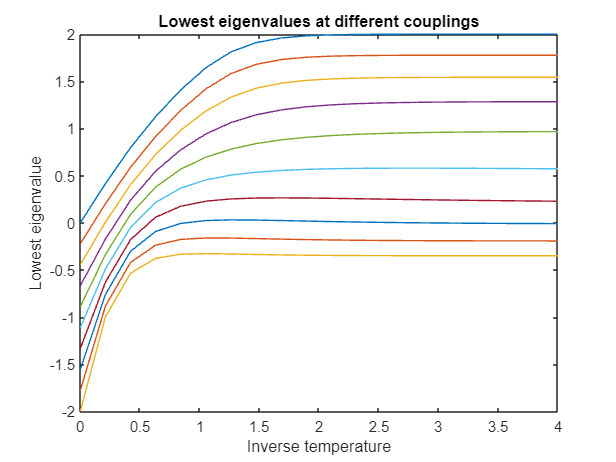

figure()
plot(bb,yy')
xlabel('Inverse temperature')
ylabel('Lowest eigenvalue')
title('Lowest eigenvalues at different couplings')

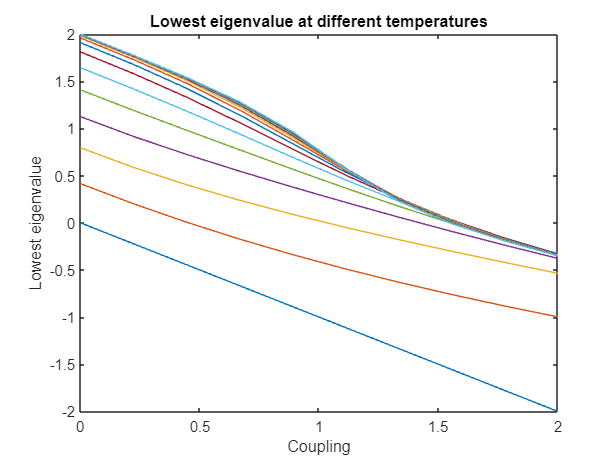


figure()
plot(gg,yy)
xlabel('Coupling')
ylabel('Lowest eigenvalue')
title('Lowest eigenvalue at different temperatures')

It thus seems that there's a value of $g$ such that, when the system tends to zero temperature, the lowest eigenvalue vanishes. And for each coupling $g$, the lowest eigenvalue is an *increasing function *with respect to the inverse temperature, which makes sense because thermal fluctuations tends to smear out correlations anyway. This can be made more concrete by considering the closed-form solutions of the finite-temperature correlation functions.

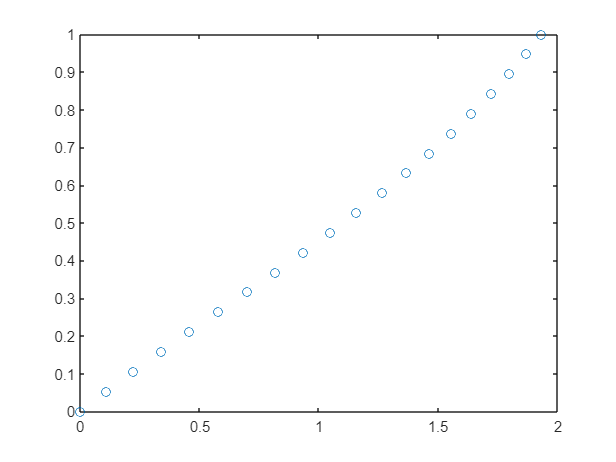


% figure()
% plot(gset, b, 'o')

% hold on
% plot(gset1, b)
% ylim([0,1])

N = 6; g = 0.8;



We should also have analytical results that can be pushed to the thermodynamic limit. 

### Functions

Compute the number operator at finite temperatures $\langle \gamma_k^\dagger \gamma_k \rangle_{\beta,\sigma}$.

function n = single_ptle_excit(b, mu, p, N, eps)
% b: inverse temperature
% mu: index of the momentum, taking integer values from 1 to N
% p: parity sector
% N: total number of particles/sites
% eps: the energy
% output n: the single-particle expectation at wavevector k

K = kk(N, p, 0); % a vector of wavevectors
k = K(mu); % the wavevector of interst
E = eps(p); % a vector of energies
omega = E(mu); % the energy of the corresponding mode
numerator = exp(-2*b*omega)/2 * ( ...
    prod_except(1+exp(-2*b*E), mu) - prod_except(1-exp(-2*b*E), mu));
denominator = prod(1+exp(-2*b*eps(0))) + prod(1-exp(-2*b*eps(0))) + ...
    prod(1+exp(-2*b*eps(1))) + prod(1-exp(-2*b*eps(1)));
% the denominator was just the full partition function
n = 4* numerator/denominator;

end

Note that the limiting behaviour is such that at infinite temperature the occupation number at all $k$ should be $1/2$, 



function K = kk(N, p, posflag)
switch p
    case 0
        K = -(N-1)/N*pi:(2*pi)/N:(N-1)/N*pi;
    case 1
        K = -pi+2*pi/N:(2*pi)/N:pi;
end
if posflag == 1
    K = K(K>=0);
end

end

function val = f(p, mu, eps, eta, i, b, Z)
E = eps(p);
e = E(mu);
switch i
    case '10'
        val = exp(-2*b*e)/2 * (prod_except(1+exp(-2*b*E), mu) - eta*prod_except(1-exp(-2*b*E), mu));
    case '01'
        val = 1/2 * (prod_except(1+exp(-2*b*E), mu) + eta*prod_except(1-exp(-2*b*E), mu));
end
val = val/Z(b);
end

function val = prod_except(A, i)
A(i) = [];
val = prod(A);
end

function z1 = EZZ(b, N, eps)
vec = zeros(2, N); % two rows for two parity sectors
for p = [0, 1]
    K = kk(N, p, 0);
    E = eps(p);
    for mu = 1:N
        vec(p+1, mu) = -2*sin(K(mu))^2/E(mu) * (single_ptle_excit(b, mu, ...
           p, N, eps) - 1/2)  + 2*cos(K(mu))* (single_ptle_excit(b, mu, ...
           p, N, eps)*(g-cos(K(mu)))/E(mu)  + 1/2 - 1/2*(g-cos(K(mu)))/E(mu));
    end
end
z1 = 1/2 * (sum(vec, 'all') * (1/N));
end

function x1 = EX(b, N, eps)
vec = zeros(2, N); % two rows for two parity sectors
for p = [0, 1]
    K = kk(N, p, 0);
    E = eps(p);
    for mu = 1:N
        vec(p+1, mu) = (g - cos(K(mu)))/E(mu) * single_ptle_excit(b, mu, ...
           p, N, eps) + 1/2 - 1/2*((g - cos(K(mu)))/E(mu));
    end
end
x1 = 1/2 * (sum(vec, 'all') * (-2/N))+1;
end

function [x, z] = gen_therm_av(N, b, g)
% ED
H = hIM(1, g, 0, N, 'PBC');
expec = @(b, O) trace(O * expm(-b*H))/trace(expm(-b*H));
z = expec(b, PauliI(N, 1, 3)*PauliI(N, 2, 3));
x = expec(b, PauliI(N, 1, 1));
end



